Sam Kramer

November 27th, 2023

Weak Signal Generator

# Weak Signal Generator

This is the notebook that will be used for the generation of the weak signals that will be used to find the relative performance of our algorithm system. This will generate a number of different signals based on the type of noise that has been injected into the signal. All will have additive gaussian noise that has been added to create a element of signal and sensor noise. There will also be process noise in the forms of deterministic trains and addtions of frequencies. All will be sampled at 100 kHz and all will have the same target signal.

To calculate the signal to noise ratio for all the different signals, we have the following definitions


$$SNR = 10log_{10}(\frac{P_s}{P_n})$$


where the $P$ of a signal is the average signal power as defined by the following:


$$P = \frac{1}{2N + 1}E_s$$



$$E_n =\sum_{i=1}^N |x_i \left(t\right)|^2$$


This is from Digital Signal Processing 4th Edition, Proakis et al. Pearson Education (pg. 47)

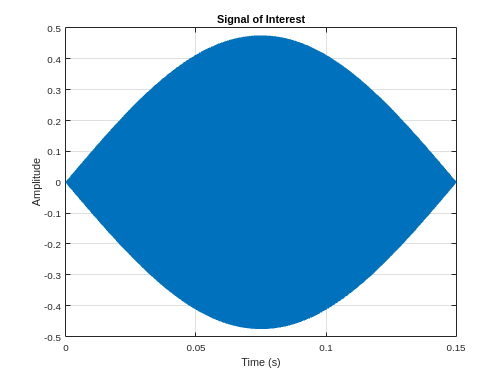

% --Setup
    clear; clc; format compact; close all;

% --Simulation Parameters
    fs = 100000;                        % Sample Frequency (Hz)
    T = 0.15;                            % Signal Period (s)
    A = 0.5;                           % Signal Amplitude (V)
    sig_freq = 20000;                   % Signal Frequency (Hz)
    f = sig_freq * 2 *pi;               % Sig Frequency (rad/s)
    t = 0:1/fs:T;                       % Signal time vector
    t_1 = linspace(0,1,length(t));      % Signal envelope time vector

% --Signal of interest creation
    envelope = sin(pi*t_1);
    signal = envelope .* A .* sin(f*t);

% --Plot signal of interest
    figure()
    plot(t, signal)
        hold on
        grid on
        title("Signal of Interest")
        xlabel('Time (s)')
        ylabel('Amplitude')

## Colored Noise: Generate Signal With many Frequencies

This type of signal is going to be generated by adding together N amount of frequencies that are all within the frequency range of interest. The idea is that these are signals that are not able to be filtered and cleaned to better detect the signals. The background noise is going to be defined as the following:


$$N=\sum_{i=1}^N A^* \sin \left(\omega_N t\right)$$


This is the definition of the signal noise and also has random gaussian noise added to the background. This will add an element of signal/sensor noise and variance in our measurement.

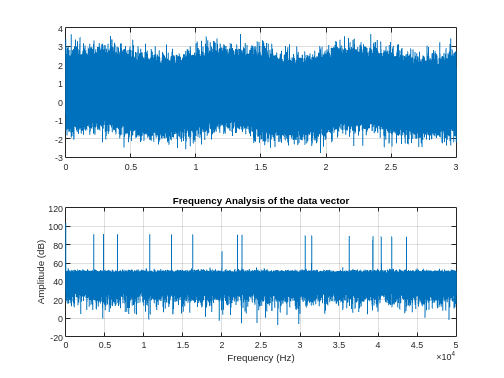

% --Define signal time vector
    time = 0:1/fs:3;
    freq = randi(50000,15,1);
    base_signal = [];
    base_signal = 0.25 .* sin(2*pi*time); 

% --For loop generating signal
    for i = 1:length(freq)
        
        add_signal = 0.25 .* sin(2.*pi.*freq(i).*time);
        base_signal = base_signal + add_signal;

    end
    additive_noise = 01 .* rand([1 length(base_signal)]);
    base_signal = (base_signal + additive_noise) ;

% % --Plot base_signal
%     figure()
%     subplot(2,1,1)
%     plot(time, base_signal)
%         hold on
%         grid on
%         xlabel('Time (s)')
%         ylabel("Amplitude")
%         title("Base Signal without signal of interest")

% --Fourier Analysis
    f_sig = abs(fft(base_signal));
    f_sig = mag2db(f_sig);
    freq = fs.*(0:length(f_sig)-1)./length(f_sig);

% % --Plot
%     subplot(2,1,2)
%     plot(freq, f_sig)
%         xlim([0 50000])
%         xlabel("Frequency (Hz)")
%         ylabel("Amplitude (dB)")
%         hold on
%         grid on
%         title("Frequency Analysis of the Base Signal")

% --Adding in the signal
    append = zeros(1, length(base_signal) - length(signal));
    signal_zp = [append(1:end/2), signal, append(end/2:end-1)];
    data = base_signal + signal_zp;

% --Plot out and display
    figure()
    subplot(2,1,1)
    plot(time,data)
        grid on 
        hold on

% --Fourier Analysis
    f_sig = abs(fft(data));
    f_sig = mag2db(f_sig);
    freq = fs.*(0:length(f_sig)-1)./length(f_sig);

% --Plot
    subplot(2,1,2)
    plot(freq, f_sig)
        xlim([0 50000])
        xlabel("Frequency (Hz)")
        ylabel("Amplitude (dB)")
        hold on
        grid on
        title("Frequency Analysis of the data vector")

% --Calculating SNR values
    base_signal_power = sum(base_signal.^2)/(2*length(base_signal) + 1);
    signal_power = sum(signal.^2)/(2*length(signal) + 1);
    SNR = 10*log10(signal_power/base_signal_power)

SNR = -11.2537

## Colored Noise: Train Wave Generation

This signal is going to be N amount of Gaussian Pulse trains that are placed in series with eachother meant to simulate a deterministic noise that is in the background of our measurement. This in theory could be a process noise that is impossible to simulate from our signal. We can also place the signal in different areas to be outside of the trains to help with the detection of the signal. The signal will also have the additive gaussian noise to the signal to simulate signal noise. There are also N amount of random low frequencies added to the signal as well. 

% --Base signals
    freq = randi(25,1,4);

% --Generating Train Signal
    tc = gauspuls('cutoff',15000,0.1); 
    t = -tc:1/fs:tc; 
    x = gauspuls(t,15000,0.1); 

% --Generating Signals with Multiple Pulse Trains
    num_trains = randi([100 500],1,1);
    pulse_signal = [];

    for i = 1:num_trains
        append = zeros(1, randi(1000,1,1));
        pulse_signal =  [pulse_signal, append, x];
    end

    time = (1/fs)*(0:length(pulse_signal) - 1);

% --Add to base frequency signals
    base_signal = [];
    for i = 1:length(freq)

        base_signal = 01 .* sin(2*pi*freq(i)*time);
        pulse_signal = pulse_signal + base_signal;

    end
    additive_noise = 01.25 .* rand([1 length(base_signal)]);
    pulse_signal = pulse_signal + additive_noise;
    pulse_signal = pulse_signal - mean(pulse_signal);

% % --Plot
%     figure()
%     plot(time, pulse_signal)
%         hold on
%         grid on
%         xlabel("Time(s)")
%         ylabel("Amplitude")
%         title("Original Pulse Train Signal")

% --Adding in the signal right in the middle
    append = zeros(1, length(pulse_signal) - length(signal));
    signal_zp = [append(1:round(end/2)), signal, append(round(end/2):end - 1)];
    data = pulse_signal + signal_zp;

% % --Plotting out new signal
%     figure()
%     plot(time, data)
%         hold on
%         grid on
%         xlabel("Time(s)")
%         ylabel("Amplitude")
%         title("Pulse Train Signal with Signal of Interest")
%     xline(length(data(1:round(end/2)))/fs, "--", "Color", [0.8 0.2 0.2])

% --Calculating SNR
    pulse_signal_power = sum(pulse_signal.^2)/(2*length(pulse_signal) + 1);
    signal_power = sum(signal.^2)/(2*length(signal) + 1);
    SNR = 10*log10(signal_power/pulse_signal_power)

SNR = -17.0291

## White Noise: Stochastic Random Signal

This is a purely stochastic noise signal that will use additive gaussian noise to obcure the signal.

% --Setup
    tmax = randi([2 7]);
    time = 0:1/fs:tmax;
    base_signal = 10 .* rand([1 length(time)]);
    base_signal = base_signal - mean(base_signal);

% --Adding in the signal right in the middle
    append = zeros(1, length(base_signal) - length(signal));
    signal_zp = [append(1:round(end/2)), signal, append(round(end/2):end - 1)];
    data = base_signal + signal_zp;
    data = data - mean(data);

% % --Plotting
%     figure()
%     plot(time, data)

% --Calculating SNR
    base_signal_power = sum(abs(base_signal).^2)/(2*length(base_signal) + 1);
    signal_power = sum(abs(signal).^2)/(2*length(signal) + 1);
    SNR = 10*log10(signal_power/base_signal_power)

SNR = -21.2533